**Dataset Import and initial analysis**

clc; clear all; close all;

% loading the file
data = readtable("MSFT_2006-01-01_to_2018-01-01.csv");
head(data)

       Date       Open     High      Low     Close      Volume        Name  
    __________    _____    _____    _____    _____    __________    ________

    2006-01-03    26.25       27     26.1    26.84    7.9974e+07    {'MSFT'}
    2006-01-04    26.77    27.08    26.77    26.97    5.7976e+07    {'MSFT'}
    2006-01-05    26.96    27.13    26.91    26.99    4.8248e+07    {'MSFT'}
    2006-01-06    26.89       27    26.49    26.91    1.0097e+08    {'MSFT'}
    2006-01-09    26.93    27.07    26.76    26.86    5.5628e+07    {'MSFT'}
    2006-01-10    26.65    27.02    26.59       27    6.4925e+07    {'MSFT'}
    2006-01-11    27.01    27.39     26.9    27.29    7.0124e+07    {'MSFT'}
    2006-01-12    27.25    27.26    26.97    27.14    4.5995e+07    

size(data)

ans =         3019           7


% removing the last column since it is a constant with value "MSFT"
data(:,end) = [];

% check missing values
missing = ismissing(data);
disp(data(any(missing, 2), :));

    Date    Open    High    Low    Close    Volume
    ____    ____    ____    ___    _____    ______




% normally there are between 250 and 252 trading days (= open stock markets) each year
years = year(data.Date);
uniqueYears = unique(years);
dateCounts = zeros(length(uniqueYears), 1); 

for i = 1:length(uniqueYears)
    dateCounts(i) = sum(years == uniqueYears(i));
end

yearlyCountsTable = table(uniqueYears, dateCounts, 'VariableNames', {'Year', 'Count'});
disp(yearlyCountsTable);

    Year    Count
    ____    _____

    2006     251 
    2007     251 
    2008     253 
    2009     252 
    2010     251 
    2011     252 
    2012     250 
    2013     252 
    2014     252 
    2015     252 
    2016     252 
    2017     251 



% dates range
dateRange = [min(data.Date) max(data.Date)];
disp(dateRange);

   2006-01-03   2017-12-29



% % Make "close" the last variable since it is the response 
% closingPrice = data.Close;
% data(:,"Close") = [];
% data.Close = closingPrice;

%Summary of the dataset
summary(data)

Variables:

    Date: 3019×1 datetime

        Values:

            Min       2006-01-03
            Median    2011-12-30
            Max       2017-12-29

    Open: 3019×1 double

        Values:

            Min         15.2  
            Median     29.99  
            Max        87.12  

    High: 3019×1 double

        Values:

            Min        15.62  
            Median     30.23  
            Max         87.5  

    Low: 3019×1 double

        Values:

            Min        14.87  
            Median     29.78  
            Max        86.23  

    Close: 3019×1 double

        Values:

            Min        15.15  
            Median        30  
            Max        86.85  

    Volume: 3019×1 double

        Values:

            Min       7.4256e+06
            Median    4.6175e+07
            Max       5.9108e+08



**Data Visualization**

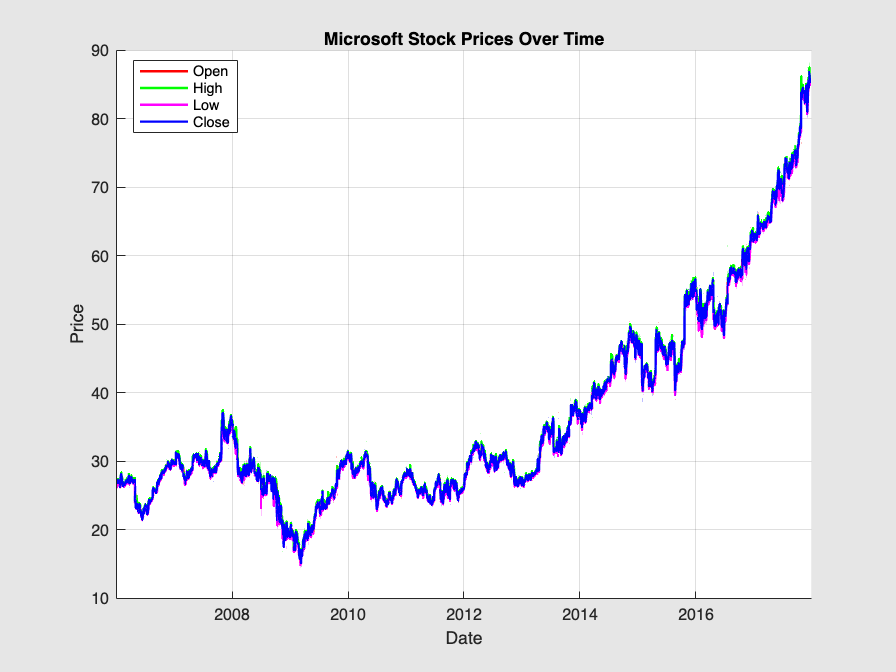

% %Convert the data table to matrix
% stocks = table2array(data(:,["Open","High","Low","Close","Volume"]));
% % keep date in a seperate datetime variable
% dateVar = table2array(data(:,"Date"));
% 
% columnNames = ["Open","High","Low","Close","Volume"];
% 
% %Histograms
% figure
% for i = 1:5
%     subplot(3,2,i)
%     histogram(stocks(:,i))
%     title(columnNames(i))
% end
%Time series analysis of each price variable
% Create a figure
figure;
hold on;

% Plot each price with a different color
set(gcf, 'Color', [0.9 0.9 0.9]); 
plot(data.Date, data.Open, 'LineWidth', 1.5, 'Color', 'red');
plot(data.Date, data.High, 'LineWidth', 1.5, 'Color',  'green');  
plot(data.Date, data.Low, 'LineWidth', 1.5, 'Color', 'magenta');  
plot(data.Date, data.Close, 'LineWidth', 1.5, 'Color', 'blue');  
% Add legend
legend('Open', 'High', 'Low', 'Close', 'Location', 'best');

% Add labels and title
xlabel('Date');
ylabel('Price');
title('Microsoft Stock Prices Over Time');
grid on;
hold off;

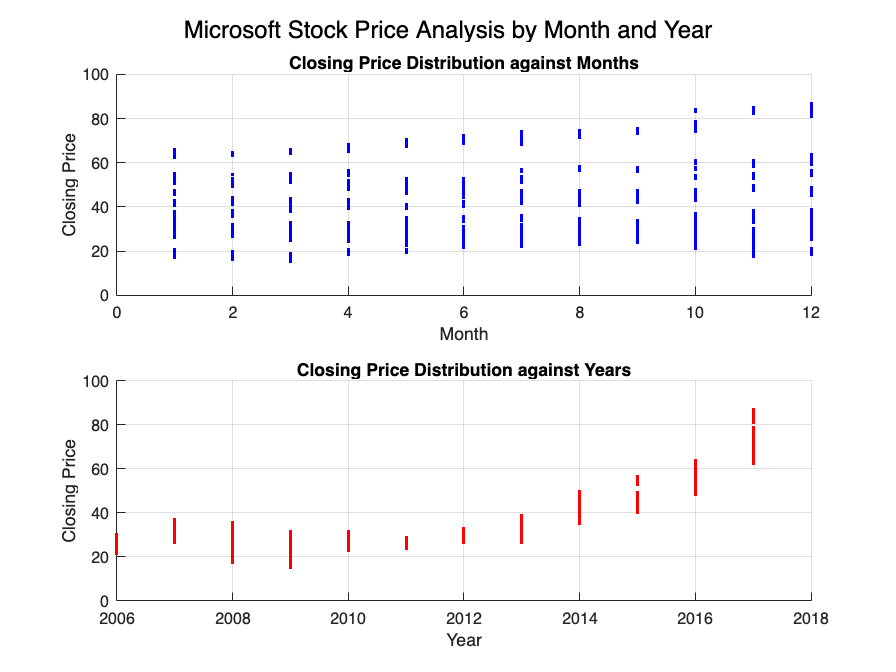


% Closing Price Distribution over the months
figure;
% Scatter plot of Closing Prices against Months
subplot(2, 1, 1);  % Create a subplot for Month vs. Close Price
scatter(month(data.Date), data.Close, 'b.');
title('Closing Price Distribution against Months');
xlabel('Month');
ylabel('Closing Price');
grid on;

% Scatter plot of Closing Prices against Years
subplot(2, 1, 2);  % Create a subplot for Year vs. Close Price
scatter(year(data.Date), data.Close, 'r.');
title('Closing Price Distribution against Years');
xlabel('Year');
ylabel('Closing Price');
grid on;

% Adjust the layout for better visibility
sgtitle('Microsoft Stock Price Analysis by Month and Year');


% % Price vs Volume
% figure;
% subplot(2,1,1)
% plot(data.Date, data{:, 'Close'});
% xlabel('Time');
% ylabel('Price');
% title('Trend Over Time of Close');
% 
% subplot(2,1,2)
% plot(data.Date, data{:, 'Volume'});
% xlabel('Time');
% ylabel('Nr of Stocks Traded');
% title('Trend Over Time of Volume');
% correlation coefficient
correlationCoefficient = corr(data.Close, data.Volume);
fprintf('The correlation between Volume and Close Price is: %.4f\n', correlationCoefficient);

The correlation between Volume and Close Price is: -0.4853


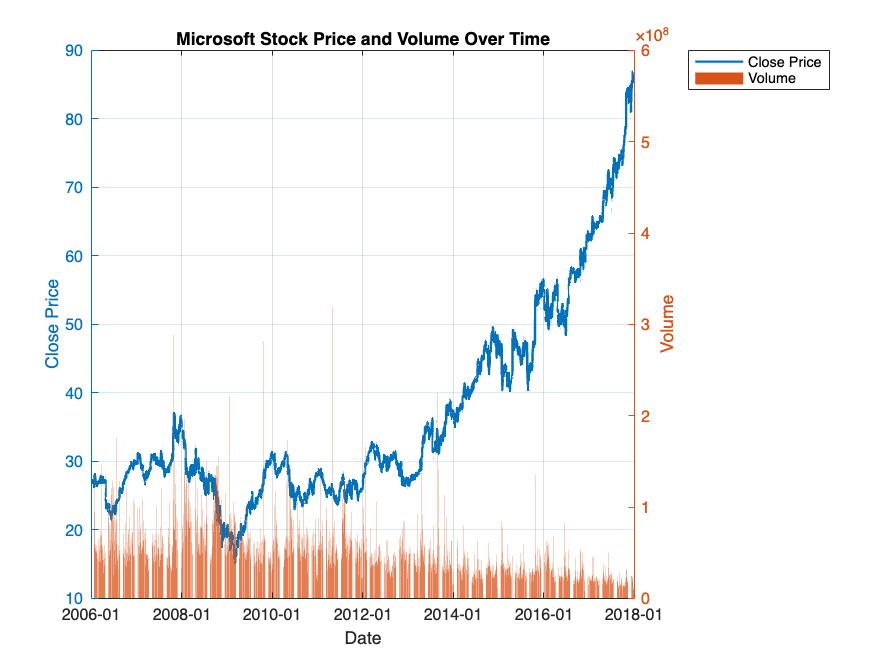

% Ensure the Date column is in datetime format
data.Date = datetime(data.Date, 'InputFormat', 'yyyy-MM-dd');

% Extract the Close price and Volume columns
closePrices = data.Close;
volume = data.Volume;
dates = data.Date;

% Create a figure
figure;
yyaxis left;  % Left y-axis for Close price
plot(dates, closePrices, 'LineWidth', 1.5);
ylabel('Close Price');
xlabel('Date');
title('Microsoft Stock Price and Volume Over Time');

% Set the left y-axis color to blue (for clarity)
ax = gca;
ax.YColor = [0 0.4470 0.7410];  % Blue color

yyaxis right;  % Right y-axis for Volume
bar(dates, volume);  % Transparent bars
ylabel('Volume');

% Set the right y-axis color to red (for clarity)
ax.YColor = [0.8500 0.3250 0.0980];  % Red color

% Formatting the x-axis and grid
datetick('x', 'yyyy-mm');  % Adjust x-axis labels to show dates
grid on;
legend('Close Price', 'Volume', 'Location', 'bestoutside');

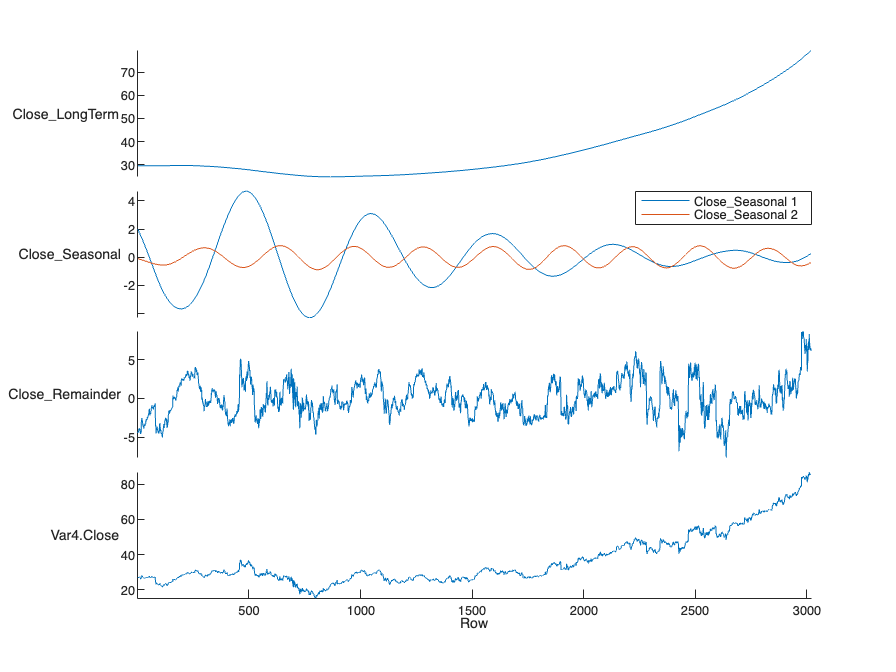

figure;
%Trend decomposition
result = trenddecomp(data(:,"Close"), NumSeasonal=2); 
result = addvars(result,data(:,"Close"));

stackedplot(result)

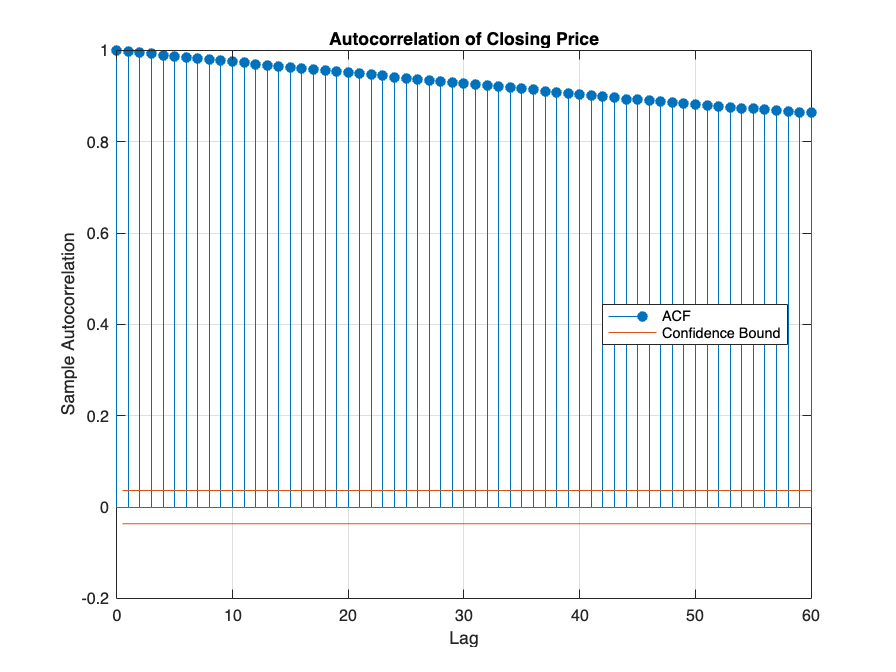

% 
 % Perform autocorrelation analysis of open variable
figure;
autocorr(data{:,'Close'}, 'NumLags', 60); 
legend('Location', 'best');
title('Autocorrelation of Closing Price');


% Define the partition ratio (80% for training and 20% for testing)
trainRatio = 0.8;

% Calculate the number of training data points
trainSize = floor(height(data) * trainRatio); % Use height(data) for the number of rows

% Split the data into training and testing sets
trainData = data(1:trainSize, :); % Specify all columns
testData = data(trainSize+1:end, :); % Specify all columns
